# Deep learning based approaches for image tampering detection

In this exercise you will detect image tampering by using convolutional neural networks. For this exercise, a basic image tampering is selected, namely the resize. This operation includes upscaling the image and cropping a region of interest to the size of the original image. Even if simple, this operation is seldom used to remove objects from the image without changing its resolution.

Some of the functions used in this livescript require the Deep Learning Toolbox™ and the Image Processing Toolbox™. If these support packages are not installed, the functions provide the download links.

% Clear workspace and command window
clear;
clc;

## Download the CIFAR-10 dataset

We are using a well-known dataset for object detection (e.g. see this [example](https://it.mathworks.com/help/deeplearning/ug/train-residual-network-for-image-classification.html#TrainResidualNetworkOnCIFAR10Example-1)).  The dataset contains of 32x32 color images from 10 classes already divided into training (50000 samples) and test (10000 samples) sets. In this lesson we will neglect the object classes since our goal is to detect image resizing. Instead, we will generate the class "resized" by manually resizing and cropping each image of the dataset.

This dataset is useful for toy examples, thanks to the small size of the images. At the same time, it contains a sufficient number of images to train either a feature-based classifier or a deep neural network.

Here, we are using a function to download the dataset (175 MB). This can take a couple of minutes.

This function can be found at the end of the script (see section *Helper Functions*).

If the automatic download fails, please manually download the data from this [link](https://www.cs.toronto.edu/~kriz/cifar-10-matlab.tar.gz).

download_CIFAR10;

## Generate the tampered dataset

Load the original CIFAR-10 dataset images (here considered as *pristine*), and generate the corresponding *tampered* data (thus doubling the dataset).

This is done only once by using the `generateTamperedData` function that can be found at the end of the script (see section *Helper Functions*).

% generate tampered data
resize_factor = 1.5;
for i=1:5
    generateTamperedData(sprintf('data_batch_%d.mat',i),resize_factor);
end
generateTamperedData('test_batch.mat',resize_factor);

### Load the dataset

In this section, the generated dataset is loaded in the workspace by means of the `loadTamperedCIFARData` function that can be found at the end of the script (see section *Helper Functions*). Different variables are instantiated for the training and test data, as well as for the images and labels. Images are stored in 4D 32-by-32-by-3-by-N matrixes, while labels are vectors of length N containing 0 for pristine images and 1 for tampered ones.

[train_images,train_labels,test_images,test_labels] = loadTamperedCIFARData(resize_factor);

### Visualize a pair of samples

In this section, you will select a test pristine image and visualize it together with its tampered version. Use the slider to select a different image.

i = 431;
pristine_sample = test_images(:,:,:,i);
tampered_sample = test_images(:,:,:,end/2+i);

% compare an image and its tampered version
figure();
subplot 121; imshow(pristine_sample); title('pristine');
subplot 122; imshow(tampered_sample); title('tampered');

### Reduce the dataset

In general, machine learning techniques benefit from more training and test data. However, to reduce the feature extraction and training time, in this exercise we have to subsample the data set.

We subsample the training and test sets by a factor of 20.

train_images = train_images(:,:,:,1:20:end);
train_labels = train_labels(1:20:end);
test_images = test_images(:,:,:,1:20:end);
test_labels = test_labels(1:20:end);

### Save images to disk

To use Deep Learning functions, images should be properly saved in a folder. In this section, you'll save the training and test images in two separate folders. For each of them, two subfolders containing the Pristine and the Tampered images will be created.

This is done by using the `writeImagesToDisk` function that can be found at the end of the script (see section *Helper Functions*).

This should be done only once. Repeat this section only when the resize_factor changes.

overwrite_images = true;
location = "cifar-10-images";   % set the default location where to save images
train_location = fullfile(location,"train"); % train subdirectory
test_location  = fullfile(location,"test");  % test subdirectory

% if the location directory already exists, ask the user wheter to
% overwrite it or not.
if exist(train_location, 'dir')
    write_images = overwrite_images;
else
    write_images = true;
end

% write the training and test images, if necessary
if write_images
    writeImagesToDisk(train_images, train_labels, train_location, 'Writing train/val images. Please wait...');
    writeImagesToDisk(test_images, test_labels, test_location, 'Writing test images. Please wait...');
end

## Train the CNN

### Check if GPU is available and configured

Use the [gpuDevice](https://www.mathworks.com/help/parallel-computing/parallel.gpu.gpudevice.html) command to check the available and selected GPUs on your system. 

gpuDevice

If no GPU is available, the training will take much more time. Consider loading the provided trained model by typing:

### Select a pre-trained convolutional neural network

In this section, you'll use the [Deep Network Designer App](https://it.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html) to apply transfer learning technique from a pre-trained Convolutional Neural Network (CNN) for the tampering detection task.

In the Designer tab:

- Select a pre-trained Convolutional Neural Network. For example, use `ResNet18`. You might need to download/install it by using the embedded Add On installer.

- Replace the last fully-connected layer (`fc1000` for `ResNet18`) with a new one and set `OutputSize` equal to 2.

- Replace the last layer (`ClassificationLayer`) with a new one (`OutputSize` should be automatically set).

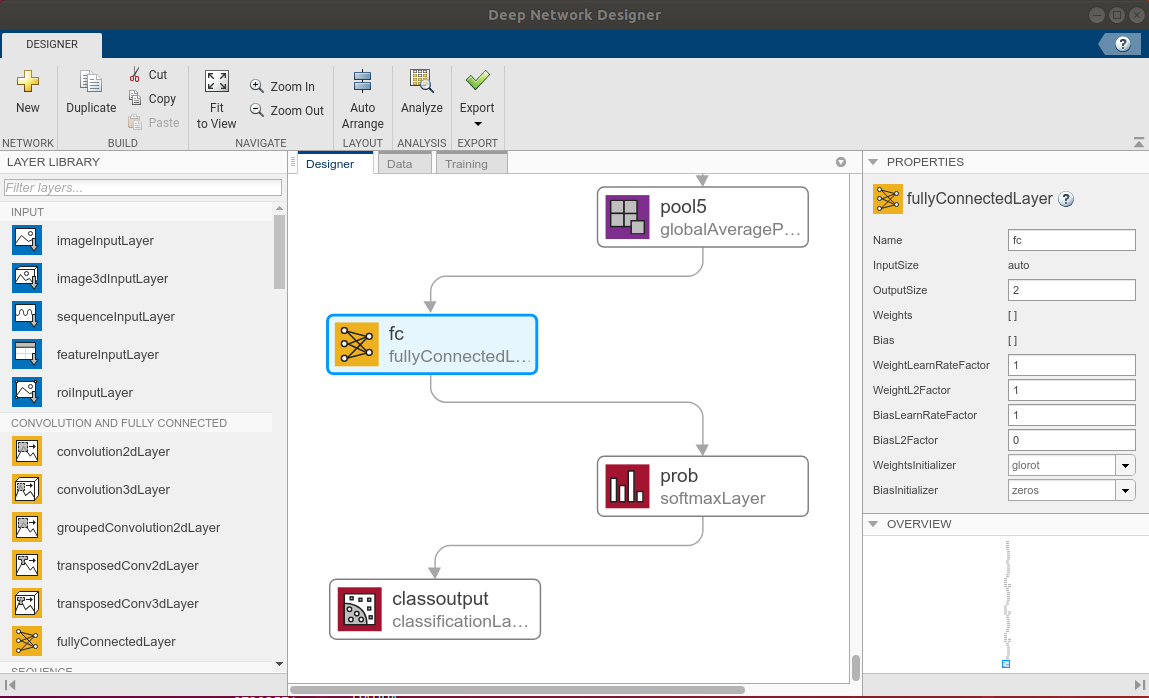

In the Data tab:

- Click on Import Data dropdown button and click on Import Image Data

- In the Training section, set Data source to Folder, browse to the train folder, and click Open.

- In the Augmentation options section, set both Random reflection axis.

- In the Validation section, Set the Percentage to 50 and check Randomize.

- Import the configuration. A few examples of the training images should appear together with the class distribution.

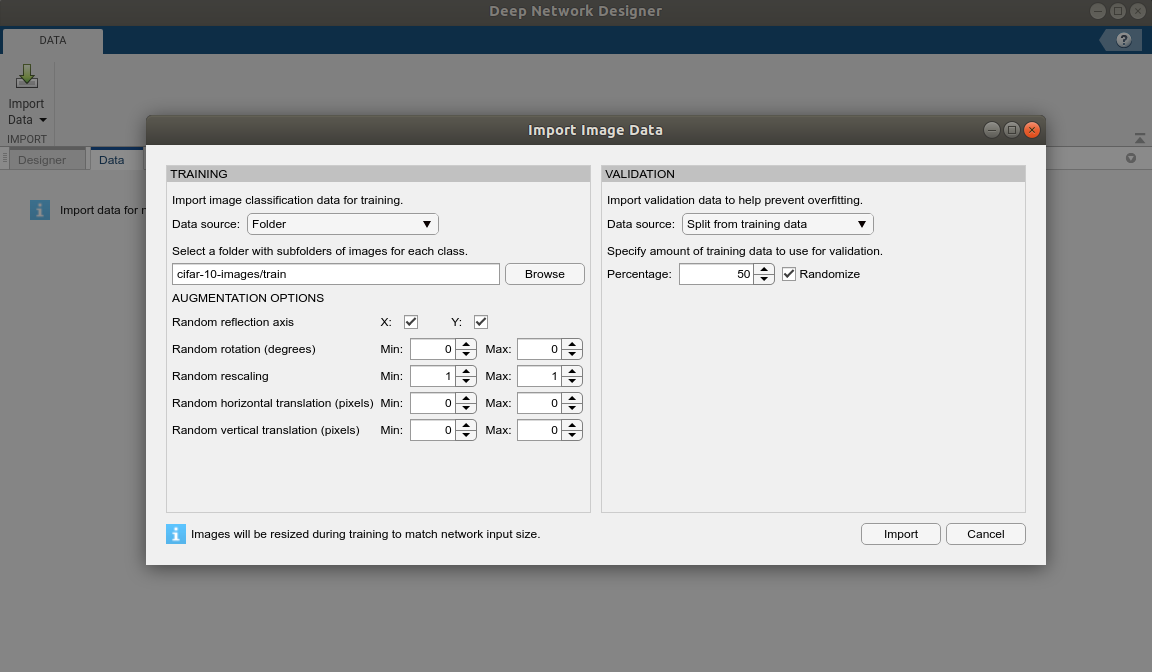

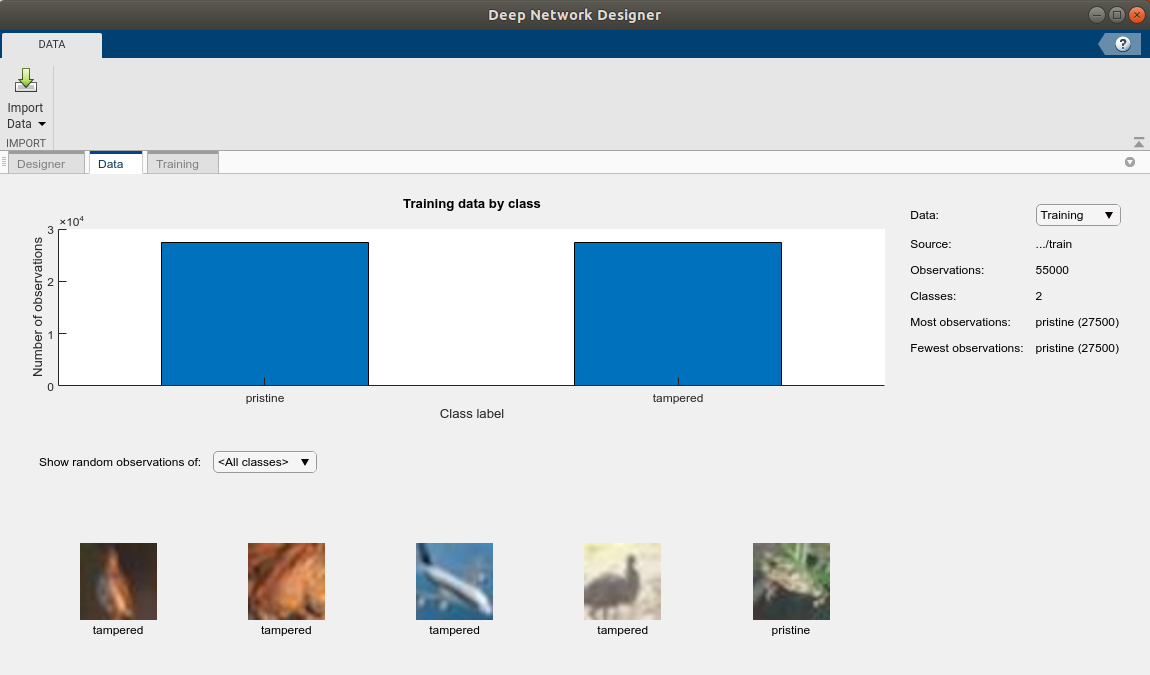

To reduce the training time, you will use 50% of the training set while leaving the remaining 50% of the data for validation. For this toy example, you'll achieve good performance on the test set. However, for more challenging problems the training set size is usually greater than that of the validation set in order to increase the generalization capabilities of the trained model.

Note that input images will be automatically resized within the app to match the input size of the selected CNN.

In the Training tab:

- Click Training Options and scroll to the Basic section.

- Set the number of epochs to 1.

- Select the ExecutionEnvironment that best fits your case (use GPU if available).

- Close the window.

- When you click Train, the training procedure will start. You should see the loss and accuracy variations during training.

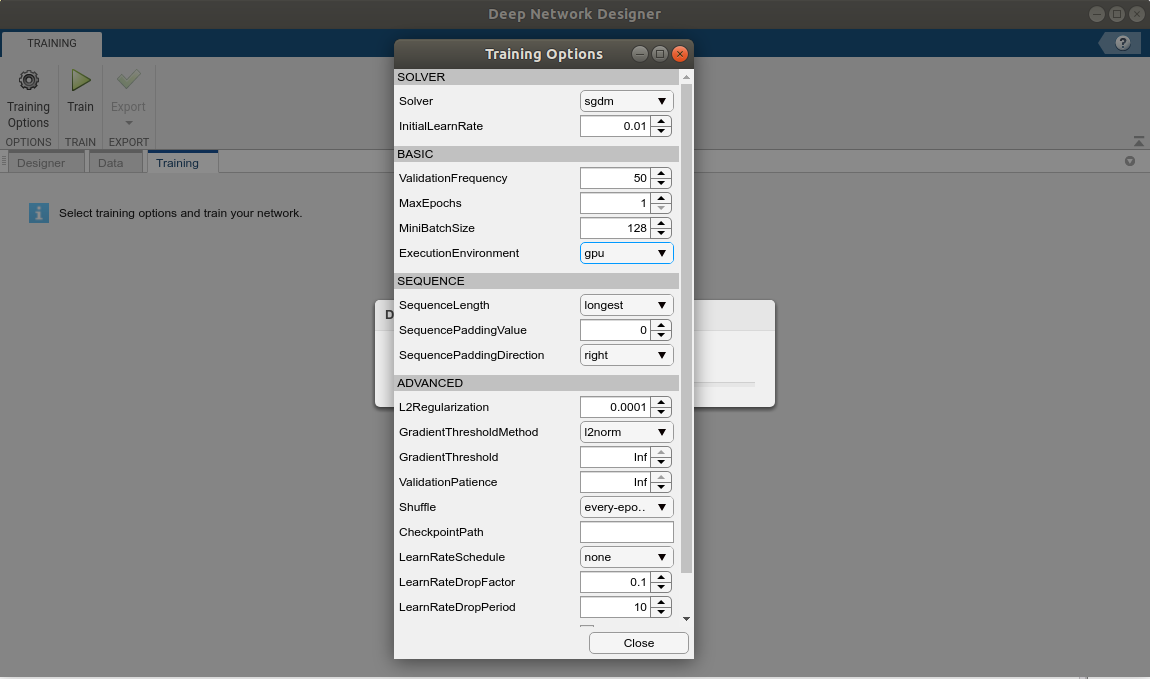

Your training should look like this:

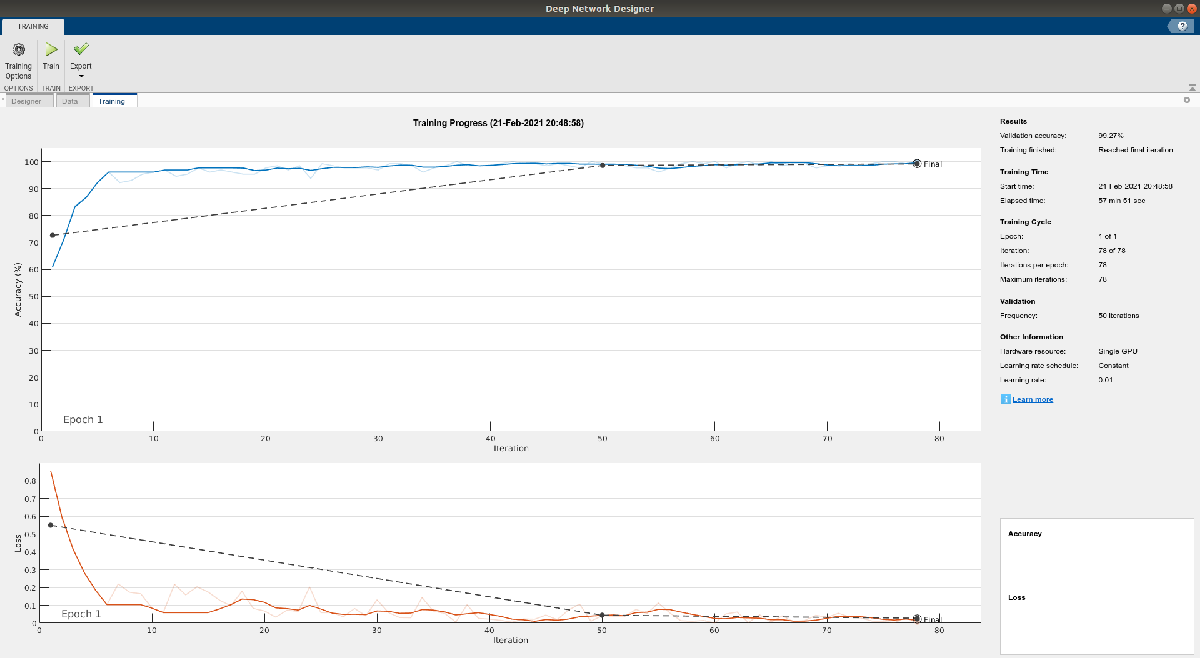

Note that to reduce the training time, you will train for just 1 epoch. For this toy example, you'll achieve good performance on the test set. However, for more challenging problems more training epochs and a stronger augmentation should be used.

### Export the trained model to workspace

Finally, export the trained network and info as `trainedNetwork` and `traininfoStruct`, respectively, as you will use them in the next steps.

Alternatively, you can load an already trainied `ResNet18` network in the workspace by loading the training_results.mat file.

loadNetwork = true;
if loadNetwork
    fprintf('\nLoading the trained network from training_results.mat... ');
    load training_results.mat;
else
    fprintf('\nLaunching the deepNetworkDesigner Appt... ');
    deepNetworkDesigner;
end
fprintf('Done.\n');

## Evaluate the trained CNN

In this section you can evaluate the performance of the trained network on the test set and plot results.

### Prepare the test data set

Use the [imageDatastore](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) function to collect test set images and their informations (e.g., labels).

testDs = imageDatastore(fullfile('cifar-10-images', 'test'),...
    'IncludeSubfolders', true,...
    'FileExtensions', '.png',...
    'LabelSource', 'foldernames');

Resize input images to match the required input size of the network (224x224 for ResNet18) by using the [augmentedImageDatastore](https://www.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html) function. 

testDs_resized = augmentedImageDatastore([224,224], testDs);

## Classify test images and evaluate network

Use the [classify](https://www.mathworks.com/help/deeplearning/ref/seriesnetwork.classify.html) function to predict labels of the test images by using the trained network.

classifiedTest = classify(trainedNetwork, testDs_resized);

Plot the results using the [confusionchart](https://it.mathworks.com/help/stats/confusionchart.html) command

figure;
confusionchart(testDs.Labels,classifiedTest, 'Title','Test set performance', 'Normalization','row-normalized');

## Further practice

- Change the `resize_factor` and run the live script again. Can you make the problem more challenging?

- Experiment with different CNNs or training parameters. Remember that deeper networks usually need more training data.

## Helper functions

### Download the CIFAR-10 dataset

If the automatic download fails, please manually download the data from this [link](https://www.cs.toronto.edu/~kriz/cifar-10-matlab.tar.gz).

Inputs:

- `downloadFolder`: path to the dataset [defaut: current directory]

Outputs:

        The dataset is saved in the *cifar-10-batches-mat* subdirectory of `downloadFolder`

function download_CIFAR10(downloadFolder)
    if nargin == 0 || isempty(downloadFolder)
        downloadFolder = './';
    end
    url = 'https://www.cs.toronto.edu/~kriz/cifar-10-matlab.tar.gz';
    filename = fullfile(downloadFolder,'cifar-10-matlab.tar.gz');
    
    dataFolder = fullfile(downloadFolder,'cifar-10-batches-mat');
    if ~exist(dataFolder,'dir')
        if ~exist(filename,'file')
            fprintf("Downloading CIFAR-10 dataset (175 MB)... ");
            websave(filename,url);
            fprintf("Done.\n")
        end
        fprintf("Extracting the CIFAR-10 dataset... ");
        untar(filename,downloadFolder);
        fprintf("Done.\n")
    end
end

### Generate the tampered samples

Load the original CIFAR-10 dataset and, for each image, generate the corresponding tampered version. This function also saves the meta information file containing the name of the classes for the binary problem.

Generation process can take a couple of minutes. This is done only once and is repeated when `resize_factor` changes.

At the end of the process, a new dataset is saved in the same directory of the original CIFAR-10 dataset.

Inputs:

- `batchFileName`: the mat file name of the original CIFAR-10 dataset

- `resize_factor`: the resize factor used to generate the tampered samples

- `downloadFolder`: path to the directory of the dataset [defaut: current directory]

Outputs:

        The dataset is saved in the *cifar-10-batches-mat* subdirectory of `downloadFolder`

function generateTamperedData(batchFileName, resize_factor, downloadFolder)
    if nargin < 3 || isempty(downloadFolder)
        downloadFolder = './';
    end
    downloadFolder = fullfile(downloadFolder, 'cifar-10-batches-mat');
    tamperedBatchFileName = strrep(batchFileName, '.mat', '.tampering.mat');
    
    % check if the dataset is already generated or not
    gen_dataset = true;  % boolean flag
    if exist(fullfile(downloadFolder,tamperedBatchFileName), 'file')
        existing_file = load(fullfile(downloadFolder,tamperedBatchFileName),'resize_factor');
        if resize_factor == existing_file.resize_factor
            % do not generate the dataset if the file exists
            % and the resize_factor is the same as input
             gen_dataset = false;
        end
    end
    
    if gen_dataset
        % Load batch as a four dimensional array
        s = load(fullfile(downloadFolder,batchFileName));
        XBatch = s.data';
        XBatch = reshape(XBatch,32,32,3,[]);
        XBatch = permute(XBatch,[2 1 3 4]);
        
        original_size = [size(XBatch, 1), size(XBatch, 2)];
        resized_size = round(original_size * resize_factor);
        
        % generate training tampered samples
        fprintf("- generating tampered samples for %s... ", fullfile(downloadFolder,tamperedBatchFileName));
        % preallocate training data
        XBatch_tampered = zeros(size(XBatch));
        % resize and crop each test image
        for i=1:size(XBatch, 4)
            % create the resized version of the original image
            im = imresize(XBatch(:,:,:,i), resize_factor);
            % random crop to the original size to obtaine the tampered sample
            win = randomCropWindow2d(resized_size, original_size);
            XBatch_tampered(:,:,:,i) = im(win.YLimits(1):win.YLimits(2), win.XLimits(1):win.XLimits(2), :);
        end
        s.data = cat(4, XBatch, XBatch_tampered);
        fprintf("Done.\n")
        
        % neglect object labels and generate binary (original vs. tampered) labels
        % for our task
        s.labels = s.labels * 0;
        s.labels = [s.labels; s.labels + 1];
        
        % set the resize factor (used to check if the dataset has to be
        % generated again or not
        s.resize_factor = resize_factor;
        
        % save the new generated data
        save(fullfile(downloadFolder,tamperedBatchFileName), '-struct', 's');
    end
    
    % save the binary classes
    if ~exist(fullfile(downloadFolder,'batches.meta.tampering.mat'), 'file')
        label_names = {'pristine'; 'tampered'};
        save(fullfile(downloadFolder,'batches.meta.tampering.mat'), 'label_names');
    end
end

### Load the CIFAR dataset together with the generated tampered samples

This function load the generated dataset composed by *pristine* (numerical label equals to *zero*) and *pristine* (numerical label equals to *one*) samples.

This function make use of `loadBatch` and `convertLabelsToCategorical` functions, defined below.

Inputs:

- `downloadFolder`: path to the dataset [defaut: current directory]

Outputs:

- `train_images`: 4D uint8 array (row, column, depth, image) containing the training images

- `train_labels`: 1D categorical array containing the training labels

- `test_images`: 4D uint8 array (row, column, depth, image) containing the test images

- `test_labels`: 1D categorical array containing the test labels

function [train_images,train_labels,test_images,test_labels] = loadTamperedCIFARData(resize_factor,downloadFolder)
    if nargin < 2 || isempty(downloadFolder)
        downloadFolder = './';
    end
    location = fullfile(downloadFolder,'cifar-10-batches-mat');
    
    if ~exist(location,'dir')
        filename = fullfile(downloadFolder,'cifar-10-matlab.tar.gz');
        if ~exist(filename,'file')
            error("Dataset not found at %s. Please download the CIFAR-10 dataset.", filename);
        else
            fprintf("Extracting the CIFAR-10 dataset... ");
            untar(filename,downloadFolder);
            fprintf("Done.\n")
        end
    end
    
    % load pristine and tampered data
    [train_images_1,train_labels_1] = loadBatch(location,'data_batch_1.tampering.mat',resize_factor);
    [train_images_2,train_labels_2] = loadBatch(location,'data_batch_2.tampering.mat',resize_factor);
    [train_images_3,train_labels_3] = loadBatch(location,'data_batch_3.tampering.mat',resize_factor);
    [train_images_4,train_labels_4] = loadBatch(location,'data_batch_4.tampering.mat',resize_factor);
    [train_images_5,train_labels_5] = loadBatch(location,'data_batch_5.tampering.mat',resize_factor);
    train_images = cat(4,train_images_1,train_images_2,train_images_3,train_images_4,train_images_5);
    train_labels = [train_labels_1;train_labels_2;train_labels_3;train_labels_4;train_labels_5];
    
    [test_images,test_labels] = loadBatch(location,'test_batch.tampering.mat',resize_factor);
end

function [XBatch,YBatch] = loadBatch(location,batchFileName,resize_factor)
s = load(fullfile(location,batchFileName));
assert(resize_factor==s.resize_factor,'File inconsistency detected. Please, generate the dataset again.')
XBatch = s.data;
YBatch = convertLabelsToCategorical(location,s.labels);
end

function categoricalLabels = convertLabelsToCategorical(location,integerLabels)
s = load(fullfile(location,'batches.meta.tampering.mat'));
categoricalLabels = categorical(integerLabels,0:1,s.label_names);
end

### Write images to disk

This function writes images to disk in the PNG format. It is performed in a parallel for loop. A `waitbar` is updated to show the progress of this operation. To this aim, this function make use of the `nUpdateWaitbar`  function, defined below.

Inputs:

- `images`: 4D array (row, column, depth, image) containing the images

- `labels`: 1D array containing the image labels

- `location`: path to the directory where the image should be saved

- `waitbar_title`: title for the waitbar (default: "writing images")

function writeImagesToDisk(images, labels, location, waitbar_title)
    if nargin < 4
        waitbar_title = "Writing images..."; % default waitbar title 
    end
    
    number_images = size(images,4); % total number of images
    
    % Create a waitbar and return its handler
    h = waitbar(0, waitbar_title);   
    % The nUpdateWaitbar updates the waitbar
    % Here we perform a dummy call to nUpdateWaitbar to initialise the waitbar
    nUpdateWaitbar(number_images, h);
    
    % To update the waitbar in a parallel loop, we define a parallel data queue
    D = parallel.pool.DataQueue;
    % The afterEach function set the operation to perform after each
    % parallel by using the data queue. Here we set the nUpdateWaitbar function
    afterEach(D, @nUpdateWaitbar);
    
    % delete location if it exists
    if exist(fullfile(location,"train"), 'dir')
        rmdir(fullfile(location,"train"), 's');
    end
    % create the directories for all the classes
    for label=unique(labels).'
        mkdir(fullfile(location,"train", char(label(1))));
    end
    
    % Start the parallel for loop
    parfor i=1:number_images
        image_path = fullfile(location,"train",char(labels(i)),sprintf('%d.png', i));
        image = images(:,:,:,i);
        image = uint8(image(:,:,1:3));
        imwrite(image, image_path);
        send(D, i); % send an increment for the waitbar to the data queue
    end
     close(h); % close the waitbar
end

### Parallel Wait Bar

Read more about this [here](https://www.mathworks.com/matlabcentral/answers/660793-help-with-parfor-progress-bar-using-data-queue).

function p = nUpdateWaitbar(data, h)
    persistent TOTAL COUNT H
    if nargin == 2
        % initialisation mode
        H = h;
        TOTAL = data;
        COUNT = 0;
    else
        % afterEach call, increment COUNT
        COUNT = 1 + COUNT;
        p = COUNT / TOTAL;
        waitbar(p, H);
    end
end